load TF_Motor.mat x
load TF_Motor.mat y
K = 0.1

K = 0.1000

Out = 0.63*K

Out = 0.0630

tau = 0.03 - 0.0205

tau = 0.0095

Te=5/1000;
    
sys = tf([10*K],[tau 1],'InputDelay',0.0205)

sys =
 
                        1
  exp(-0.0205*s) * ------------
                   0.0095 s + 1
 
Continuous-time transfer function.



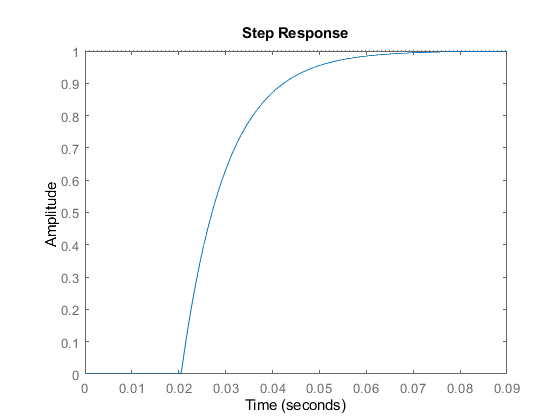

%sys = tf([K],[tau 1])
step(sys);


% pidTuner(sys,'PID')
% 
mypi = pidtune(sys,'pi')

mypi =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 0.279, Ki = 26.6
 
Continuous-time PI controller in parallel form.



% step(feedback(mypi*sys,1))

sys_d=c2d(sys,Te,'zoh')

sys_d =
 
           0.3773 z + 0.03193
  z^(-5) * ------------------
               z - 0.5908
 
Sample time: 0.005 seconds
Discrete-time transfer function.



%sys_d_bf=feedback(sys_d*K,1,-1)

C0 = pid(0.279,26.6,'Ts',Te,'IFormula','BackwardEuler');  
C = pidtune(sys_d,C0)

C =
 
             Ts*z 
  Kp + Ki * ------
              z-1 

  with Kp = -0.0025, Ki = 1, Ts = 0.005
 
Sample time: 0.005 seconds
Discrete-time PI controller in parallel form.

